# **3D visualisation of APT data**

The starting situation is a loaded pos file, loaded colorScheme, and a ranged mass spectrum (spec), see live script ***FirstSteps***.

If you start here you have to load clolorScheme and pos file. To load an your ranged mass spectrum figure pull it in your comandline. Then select the the mass spectrum and enter: *spec = gco;*

load colorScheme.mat
pos = posToTable;

Section of ranged mass spectrum of exemplary APT data set (not provided):

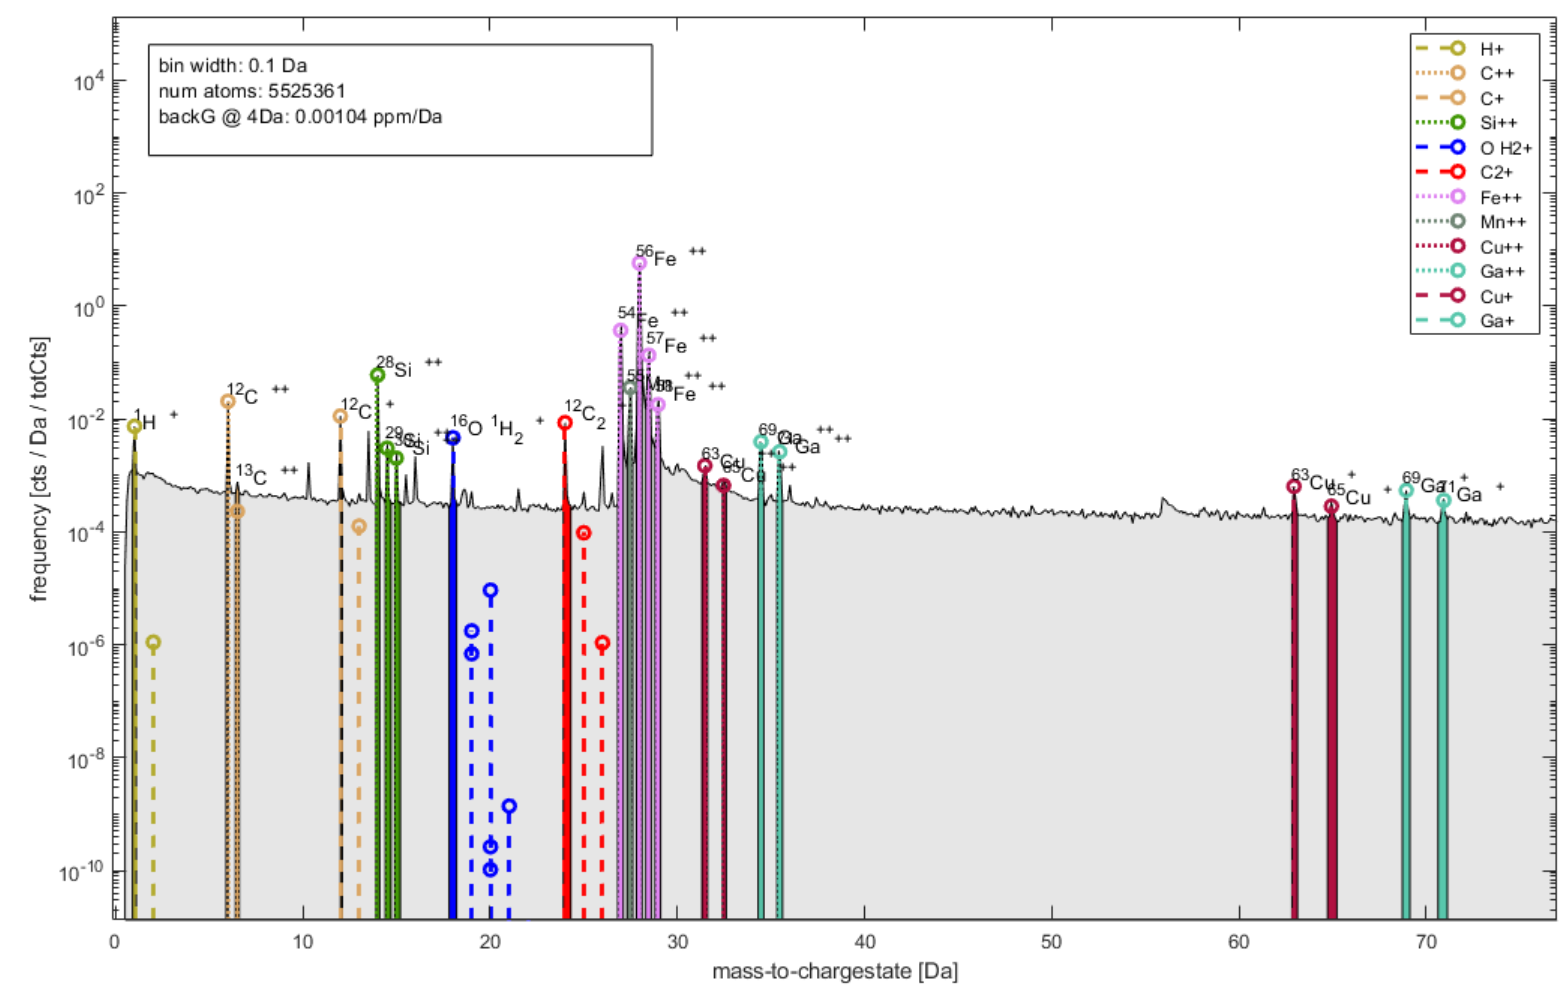

Then ranges must be extracted and the pos file needs to be parsed so that a column with *'ion'* is generated.

rng = rangesExtractFromMassSpec(spec);
pos = posAllocateRange(pos, rng, options);

For the subsquent 3D visualisation, the function *scatterPlotPosData* is needed.

*[p, ax] = scatterPlotPosData(pos,species,sample,colorScheme,size,plotAxis);*

**Examples with exemplary data set:**

- Only C atoms: *[p, ax] = scatterPlotPosData(pos, 'C', 1, colorScheme, 26);*

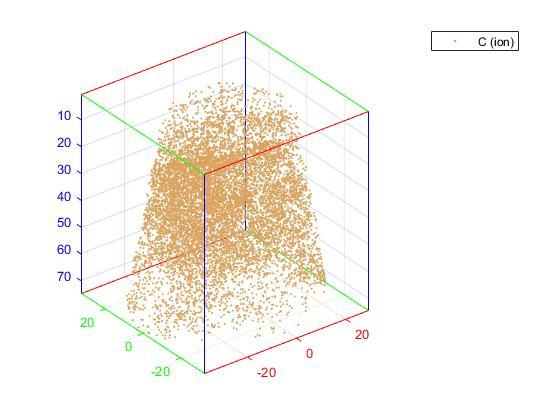

- C and Mn atoms in **two separate plots** (no *plotAxis* input): *[p, ax] = scatterPlotPosData(pos, {'C', 'Mn'}, 0.1, colorScheme, 26);*

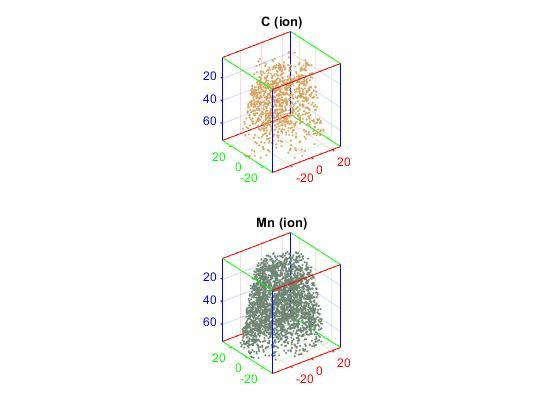

- C and Mn atoms in **one plot **(with plotAxis input): *[p, ax] = scatterPlotPosData(pos, {'C', 'Mn'}, 0.1, colorScheme, 26, ****axes(figure())****);*